clear, clc, close all;
% 测试数据
W = ones(7) * inf; 
for i = 1:7
    W(i,i) = 0;
end
W(1,2) = 4; W(1,3) = 6; W(1,4) = 5;
W(2,1) = 4; W(2,3) = 1; W(2,5) = 7;
W(3,1) = 6; W(3,2) = 1; W(3,4) = 2; W(3,5) = 5; W(3,6) = 4;
W(4,1) = 5; W(4,3) = 2; W(4,6) = 5;
W(5,2) = 7; W(5,3) = 5; W(5,6) = 1; W(5,7) = 6;
W(6,3) = 4; W(6,4) = 5; W(6,5) = 1; W(6,7) = 8;
W(7,5) = 6; W(7,6) = 8; 
% 邻接矩阵
W

W =      0     4     6     5   Inf   Inf   Inf
     4     0     1   Inf     7   Inf   Inf
     6     1     0     2     5     4   Inf
     5   Inf     2     0   Inf     5   Inf
   Inf     7     5   Inf     0     1     6
   Inf   Inf     4     5     1     0     8
   Inf   Inf   Inf   Inf     6     8     0


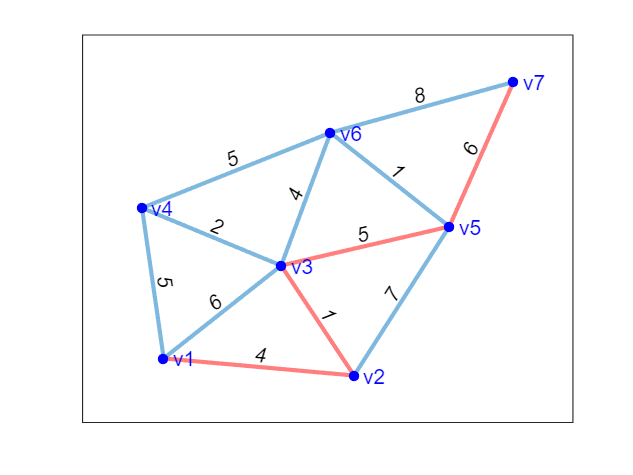


% 例：以点1为起点，点7为终点，求最短路径
start = 1;
stop = 7;
[D, P, dis, path] = fun_Floyd(W, start, stop);

% 路由矩阵
P

P =      1     2     2     4     2     2     2
     1     2     3     3     3     3     3
     2     2     3     4     5     6     5
     1     3     3     4     6     6     6
     3     3     3     6     5     6     7
     3     3     3     4     5     6     5
     5     5     5     5     5     5     7


% 最短距离矩阵
D

D =      0     4     5     5    10     9    16
     4     0     1     3     6     5    12
     5     1     0     2     5     4    11
     5     3     2     0     6     5    12
    10     6     5     6     0     1     6
     9     5     4     5     1     0     7
    16    12    11    12     6     7     0
